# **TO- Snow Emission Model**

**Divya Kumawat and Ardeshir Ebtehaj**

**University of Minnesota**

**July 2023**

## **About**

This emission model expands the well-known tau-omega model to properly simulate L-band microwave emission of the soil-snow-vegetation continuum through a closed-form solution of Maxwell's equations, considering the intervening dry snow layer as a loss-less medium. In the TO-snow emission model, the simulated brightness temperatures $$T_{\rm B}^p$$ at polarization $$p$$ comprise three components: (i) upwelling soil emission, (ii) reflected downwelling vegetation emission with multiple reflections and refractions at the soil-snow and snow-vegetation interfaces undergoing single way (zeroth-order) attenuation by the vegetation canopy, and (iii) the upwelling emission by the canopy layer.

The model simulates the brightness temperature $$T_{\rm B}^p$$ at the top of the canopy as follows:


$$
T_{\rm B}^p ={\overbrace{T_{\rm g} e^{\,p} \gamma}^{(1)}+\overbrace{T_{\rm c}(1-\omega)(1-\gamma)r^{p}\gamma}^{(2)}+ \overbrace{T_{\rm c}(1-\omega)(1-\gamma)}^{(3)}}
$$


where the upwelling surface emission is $$T_{\rm g}e^{p}\gamma$$, in which $$T_{\rm g}$$ is the effective ground temperature, $$e^p$$ denotes the incoherent component of effective emissivity of the soil-snow system, and $$\gamma = \exp(-\tau \sec \alpha_i)$$ is the vegetation transmissivity as a function of VOD ($$\tau$$) and observation angle $$\alpha_i$$ relative to nadir. The upwelling vegetation emission is $$T_{\rm c}(1-\omega)(1-\gamma)$$ where $$T_{\rm c}$$ is the canopy temperature and $$\omega$$ is the vegetation single scattering albedo. The downwelling vegetation emission reflected by the soil-snow layers is $$T_{\rm c}(1-\omega)(1-\gamma)r^p\gamma$$, in which $$r^p$$ is the incoherent component of effective surface reflectivity of the soil-snow system.

To compute the effective $$e^p$$ and $$r^p$$ of the soil-snow system, we used a coherent two-layer composite reflection model, considering a single-layer representation of dry snowpack,  without accounting for the effects of snow layering. As is evident, if $$d_{\rm s}$$ varies more than 10 cm, within the field of view of the radiometer, it is reasonable to assume that the surface emission is incoherent with respect to depth and can be represented as:

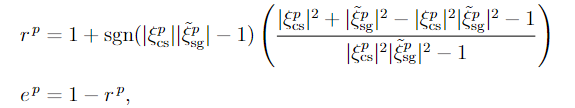

where $$\text{sgn}(\cdot)$$ denotes the signum function, $ $\xi^p_{\rm cs}$$ is the Fresnel field reflection coefficient of the canopy-snow (cs) interface, and $$\tilde{\xi}_{\rm sg}^p$$ denotes the rough reflection coefficient at the snow-ground (sg) interface.

## Forward Simulation

clear; clc;
Tcanopy =   265;        % Temperature of the canopy [K]
tau = 0.1;              % Vegetation Optical Depth (VOD)
omega = 0.07;           % Single scattering vegetation albedo
h = 0.15;               % Roughness parameter (Q/H roughness)
freq= 1.4;              % Frequency at L-band [GHz]
obs_angle = 40;         % Observation angle
Tsoil = 265;            % Temperature of soil
rho_s = 250;            % Density of snowpack
epsr_ground = 5 -0.5i;  % Dielectric constant of ground

Tb= TO_snow(Tcanopy,tau,omega,h,freq,obs_angle,Tsoil,rho_s,epsr_ground);


## Sensitivity Analysis

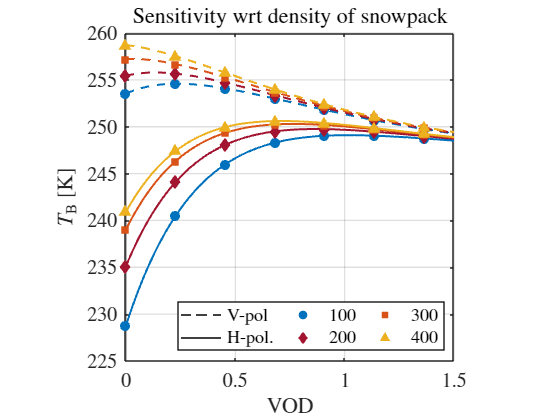

clear; clc;

Tcanopy =   265;
omega = 0.07;
h = 0.3;
freq= 1.4;
obs_angle = 40;
Tsoil = 270;
density = [100,200,300,400];
tau = linspace(0,1.5,100);
epsr_ground = 5 -0.5i;

for i = 1: length(density)
    for j = 1: length(tau)
        Tb1(:,j,i) = TO_snow(Tcanopy,tau(j),omega,h,freq,obs_angle,Tsoil,density(i),epsr_ground);
    end
end


% Plot Figure
figure;
color = [0 0.4470 0.7410; 0.6350 0.0780 0.1840; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250];
marker = {'o', 'diamond', 'square','^'};
linewidth=1.5;
for i = 1: length(density)
    ph = plot(tau,Tb1(2,:,i),...
        LineStyle='none', Color=color(i,:)); hold on;
    ph(1).LineStyle='--'; ph(1).LineWidth=linewidth;
    ph(1).Marker=marker(i); ph(1).MarkerIndices=1:15:length(tau); ph(1).MarkerFaceColor=color(i,:);
end
hold on
for i = 1: length(density)
    ph = plot(tau,Tb1(1,:,i),...
        Color=color(i,:),LineStyle = 'none'); hold on;
    ph(1).LineStyle='-'; ph(1).LineWidth=linewidth;
    ph(1).Marker=marker(i); ph(1).MarkerIndices=1:15:length(tau); ph(1).MarkerFaceColor=color(i,:);
end
title('Sensitivity wrt density of snowpack','FontSize',15,'Interpreter','latex')
xlabel('VOD','FontSize',15,'Interpreter','latex')
ylabel('$T_{\rm B}$ [K]','FontSize',15,'Interpreter','latex')
set(gca,'Fontsize',15,'TickLabelInterpreter','latex','LineWidth',1)
axis("square");
grid on;
ax2(1) = plot(nan,nan,'--',Color = 'k');
ax2(2) = plot(nan,nan,'-',Color = 'k');
for i = 1: length(density)
    ax1(i) = scatter(nan(1,3),nan(1,3),MarkerEdgeColor = color(i,:),Marker = marker(i),MarkerFaceColor=color(i,:)); hold on;
end
legend([ax2,ax1],{'V-pol','H-pol.','100','200','300','400'},...
    "Interpreter","latex","Location","southeast",Orientation="vertical",NumColumns=3);
set(gca,'Fontsize',15,'TickLabelInterpreter','latex','LineWidth',1)
axis("square")